# Script pour identifier transfert function du moteur

## Definition du model avec Te=0.1

Te=0.1;

sortie=sim("model.slx"); %30 seg d'execution avec STEP=5

## Utilisation ident et recuperation des transfer fuctions

DataSortie=sortie.sortie.Data;

Unable to resolve the name sortie.sortie.Data.

DataEntre=sortie.entre.Data;
Time=sortie.sortie.Time;
plot(Time,[DataEntre,DataSortie])
ident; % session saved in IdentStepMoteur.sid

## SBPA

%%Tf2 has best performance
G  = tf([tf3.Numerator],[tf3.Denominator]); %%Function trouve avant
S  = stepinfo(G);

N       = 5;
Tr      = S.SettlingTime*2;
Ts      = Tr/20;
P       = 4;
Plot    = 1;
[u1,t1] =prbs(Ts,N,Tr,P,Plot);
SBPA=[(t1'), u1];
SBPA=SBPA.*3;
 

% Execution du model avec SBPA

sor=sim("modelSBPA.slx") %30seg

Simulation aborted

## Utilisation ident et recuperation de transfer fuctions

SBPASortie=sor.sortieSBPA.Data;
SBPAEntre=sor.entreSPBA.Data;
Time=sor.sortieSBPA.Time;

plot(Time,[SBPAEntre,SBPASortie])
ident; % session saved in IdentSBPAMoteur.sid
Gf=tf([tf2SBPA.Numerator],[tf2SBPA.Denominator])

## Discretitation des transfert fuctions

T=59; % Trouvé a TP4 moteur
K=4.68;

Kp=(2*T-Te)/(K*Te);

GzMain=tf([K],[T/Te (1-T/Te)],Te) %Transfert function calculee a la main (voir TP3)

GzMain =
 
     4.68
  -----------
  590 z - 589
 
Sample time: 0.1 seconds
Discrete-time transfer function.



GzStep= tf([tf3.Numerator],[tf3.Denominator],Te) %Transfert fuction ident/Step
GzSBPA=tf([tf2SBPA.Numerator],[tf2SBPA.Denominator],Te) %Transfert fuction ident/SBPA

GzSBPA =
 
    2.915
  ---------
  z + 4.856
 
Sample time: 0.1 seconds
Discrete-time transfer function.



GzSBPA1=tf([tf1SBPA.Numerator],[tf1SBPA.Denominator],Te) %deux poles et un zero

GzSBPA1 =
 
     5.086 z + 65.74
  ---------------------
  z^2 + 31.74 z + 104.9
 
Sample time: 0.1 seconds
Discrete-time transfer function.



GzMain =
 
     4.68
  -----------
  590 s - 589
 
Continuous-time transfer function.



GzStep =
 
    2.895
  ---------
  s + 3.546
 
Continuous-time transfer function.



GzSBPA =
 
    2.915
  ---------
  s + 4.856
 
Continuous-time transfer function.



GzSBPA1 =
 
     5.086 s + 65.74
  ---------------------
  s^2 + 31.74 s + 104.9
 
Continuous-time transfer function.



## Analysis des transfert functions

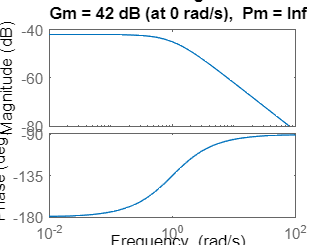

%1) Gzmain 
 sisotool(GzMain)
 margin(GzMain)

 P=pole(GzMain)

P = 0.9983

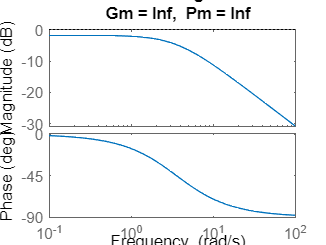

%2) GzStep
sisotool(GzStep)
margin(GzStep)

P=pole(GzStep)

P = -3.5462

%3) GzSBPA
sisotool(GzSBPA)
margin(GzSBPA)
P=pole(GzSBPA)

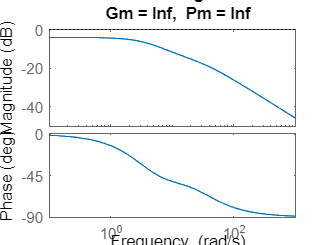

%4) GzSBPA1
sisotool(GzSBPA1)
margin(GzSBPA1)

P=pole(GzSBPA1)

P =   -27.9919
   -3.7464


## Correcteurs

%P, PI, PID
%P c'est pas possible pcq il y aurait un erreur statique constantes tjrs

%PI

%PI 1 Tuning PID avec 800ms response time 

PI1=tf([30.36 -0.8978*30.36],[1 -1],Te)

PI1 =
 
  30.36 z - 27.26
  ---------------
       z - 1
 
Sample time: 0.1 seconds
Discrete-time transfer function.




% H=(PI1*GzMain)/(PI1*GzMain+1)
% margin(H)
% stepplot(H)

%PI 2 Tuning PID avec 600ms response time et plus agresive 
PI2=tf([27.258 -0.4569*27.258],[1 -1],Te)

PI2 =
 
  27.26 z - 12.45
  ---------------
       z - 1
 
Sample time: 0.1 seconds
Discrete-time transfer function.




%PID 1 
PID1=tf([0.2755 -0.5487 0.2733],[1 -1.996 0.9963],Te) 

PID1 =
 
  0.2755 z^2 - 0.5487 z + 0.2733
  ------------------------------
      z^2 - 1.996 z + 0.9963
 
Sample time: 0.1 seconds
Discrete-time transfer function.




%PID 2 0.7 response time 0.3 robust

PID2=tf([16.18 0.8317 -15.35],[1 -1.121 0.1208],Te)

PID2 =
 
  16.18 z^2 + 0.8317 z - 15.35
  ----------------------------
     z^2 - 1.121 z + 0.1208
 
Sample time: 0.1 seconds
Discrete-time transfer function.




%PI fait a la main

PImain=tf([1],[-0.0503 1],Te)

PImain =
 
       -1
  ------------
  0.0503 z - 1
 
Sample time: 0.1 seconds
Discrete-time transfer function.



## Test simulee

PIDsimulee=tf([2.2034 2.2034*10.96],[1 0],Te)

PIDsimulee =
 
  2.203 z + 24.15
  ---------------
         z
 
Sample time: 0.1 seconds
Discrete-time transfer function.




H=(PIDsimulee*GzStep)/(1+(PIDsimulee*GzStep))

H =
 
     6.378 z^3 + 92.52 z^2 + 247.9 z
  -------------------------------------
  z^4 + 13.47 z^3 + 105.1 z^2 + 247.9 z
 
Sample time: 0.1 seconds
Discrete-time transfer function.



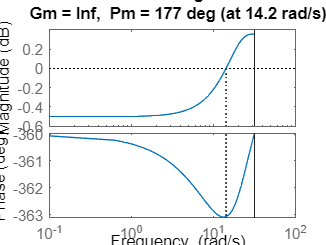

margin(H)

sisotool(H)